# Fourier Series Lab

 **Exercise. **Solve for the Fourier series of the odd sawtooth function (pictured below) with period $2L$. Then, follow the instructions to plot the Fourier series.

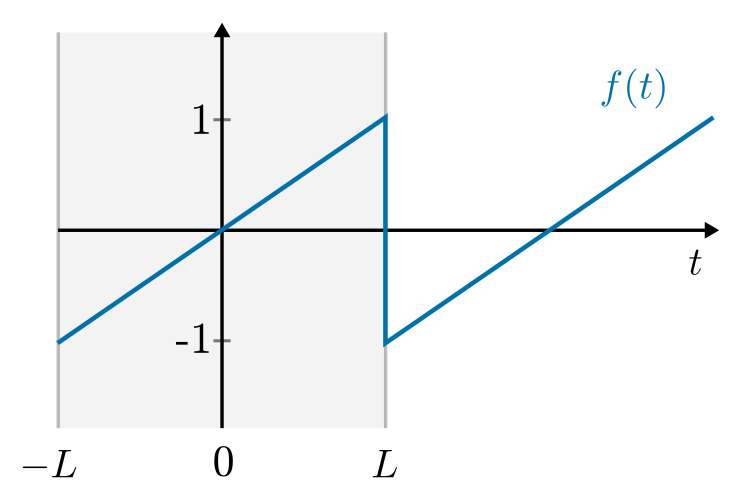

Note that on the interval $[-L,L]$ (where the integral is evaluated), the sawtooth function is simply the linear function:


$$f(t) = \frac{t}{L}$$


**---Solution---**

The function is odd so $a_n = 0$ and


$$\begin{array}{rl}
b_n &= \frac{1}{L} \int_{-L}^{L} \frac{t}{L} \sin \left( \frac{n \pi }{L} t \right) dt 
\\
&=  - \frac{2}{\pi^2 n^2} (\pi n \cos(\pi n) - \sin(\pi n))
\\
&=  - \frac{2 (-1)^n}{\pi n} 
\end{array}$$


So the Fourier series is


$$f_s(t) = \sum_{n=1,3,5,\ldots}^\infty -\frac{2(-1)^n}{n \pi} \sin \left( \frac{ n \pi } {L}  t \right)$$


**---End Solution---**

To plot the result, complete the code below by writing the expression for the Fourier series coefficients and the Fourier series terms. If your solution and code is correct, your Fourier series should approach the sawtooth function.

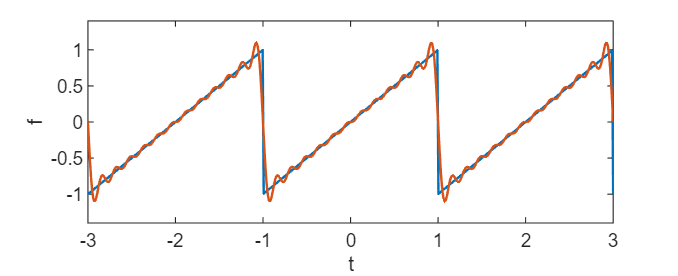

NModes = 12; % How many modes to use
% Compute the coefficients
L = 1;
n = 1:NModes;
% Replace the "NaN" with your expression for the coefficients
b = -2*(-1).^n./(n*pi); %NaN;

% Sum the Fourier modes
t = linspace(-3*L,3*L,500);
fs = zeros(size(t));
for k = 1:numel(n)
    % This loop sums over the Fourier series
    % Replace "NaN" with your expression for the Fourier series
    fs = fs + b(k)*sin(n(k)*pi/L*t);
end
f = sawtooth((t-1)*pi/L);

% Plot the result
figure("position",[1,1,800,325])
plot(t,f,t,fs,"linewidth",1.1)
axis([-3*L,3*L,-1.4,1.4])
xlabel("t")
ylabel("f")